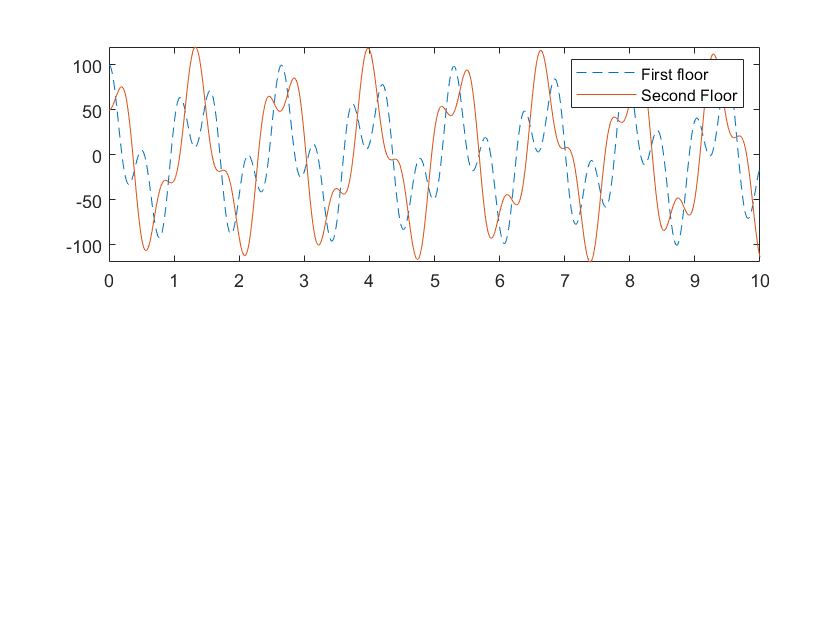

clear
 %inital values and state matrix
 k1 = 4.66; k2 = 4.66;
 m1 = 0.0917; m2 = 0.0765;
 x1i = 100 ; x2i = 50 ;
 A = [0 0 1 0 ; 0 0 0 1; (-k1-k2)/m1 k2/m1 0 0 ; k2/m2 -k2/m2 0 0 ];
 T = 10;
 %loop for graphing the two storey dynamics
 subplot(2,1,1)
 n=1000;
 incr = 10/n;
 [xr,yr,zr,wr,tr] = IEM(x1i,x2i,incr,A);
 plot(tr,xr,'--');
 hold on 
 plot(tr,yr,'-');
 legend("First floor","Second Floor")

 %figure
 %plot(tr,zr) 
 %figure
 %plot(tr,wr)
 
 

function [x,y,z,w,ti] = IEM(x1_0,x2_0,dt,A)
t= 0:dt:10;

SOL = NaN(4,length(t));
SOL(1,1) = x1_0;
SOL(2,1) = x2_0;
SOL(3,1) = 0;
SOL(4,1) = 0;

for k= 2 :length(t)
    M = SOL(:,k-1) + dt*A*SOL(:,k-1);
    SOL(:,k) = SOL(:,k-1) + (dt/2)*(A*(SOL(:,k-1)) + A*M);
end
x = SOL(1,:);
y = SOL(2,:);
z = SOL(3,:);
w = SOL(4,:);
ti = t;
end